# Exercise 3

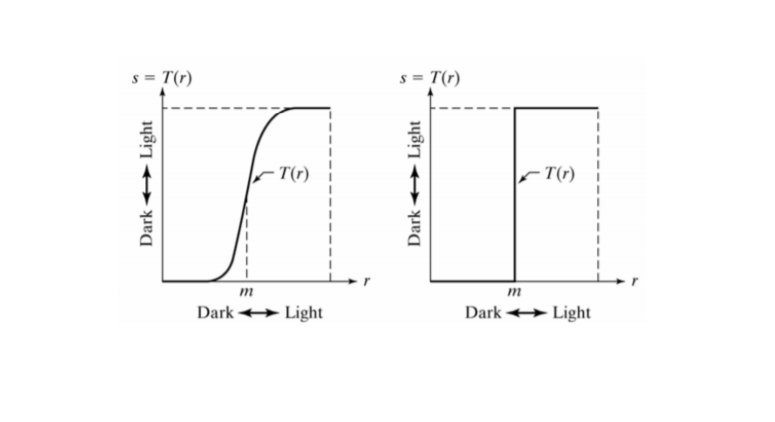

graph=imread('graph.png');
imshow(graph)

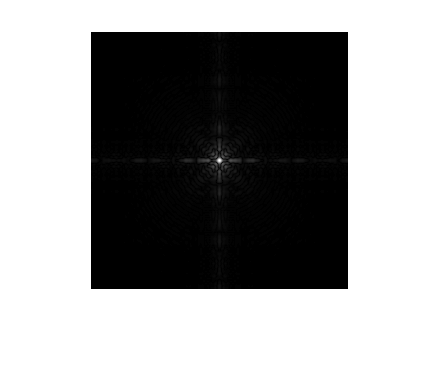

im=imread('spectrum.tif');
imshow(im)

for E=0.5 and m=0.500000

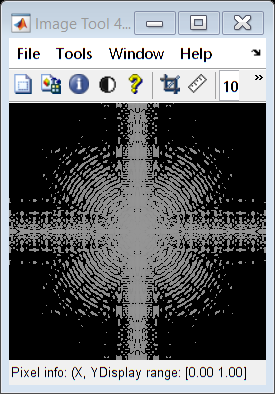

for E=0.5 and m=10.000000

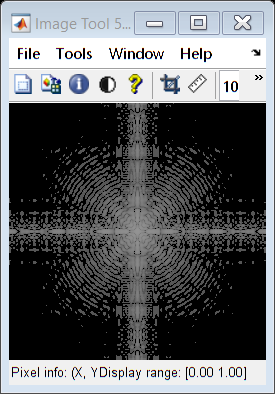

for E=0.5 and m=100.000000

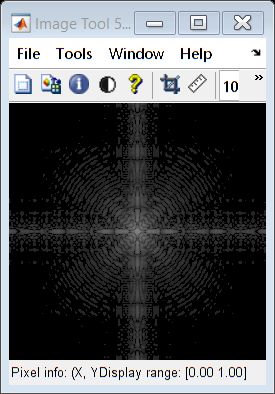

for E=0.5 and m=250.000000

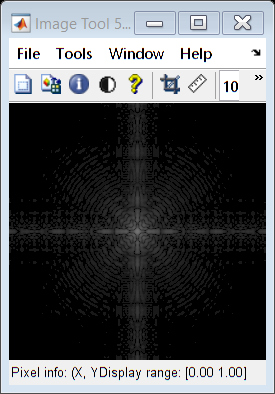


eps=0.5;
E=0.5;
%hoe kleiner m hoe meer aan de light kant we zitten
for m=[0.5 10 100 250]
    fprintf("for E=0.5 and m=%f",m)
    g=1./(1+(m./double(im)+eps).^E);
    imtool(g)
end


imshow(graph)

for m=100 and E=0.100000

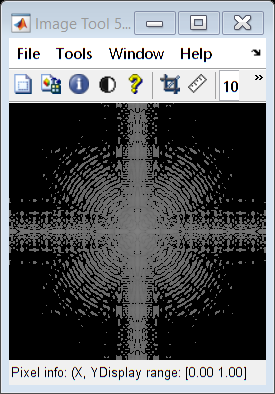

for m=100 and E=0.500000

for m=100 and E=0.800000

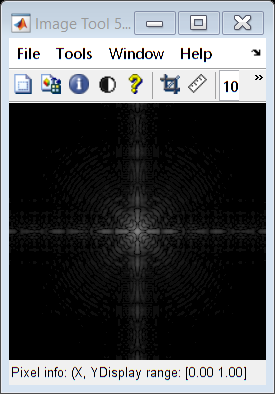

for m=100 and E=1.500000

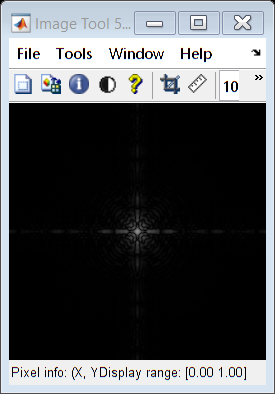

m=100;

%hoe kleiner E hoe groter de afvlakking, bij E groter dan 1 hebben we
%verticale lijn met m als treshold
for E=[0.1 0.5 0.8 1.5]
    fprintf("for m=100 and E=%f",E)
    g=1./(1+(m./double(im)+eps).^E);
    imtool(g)
end

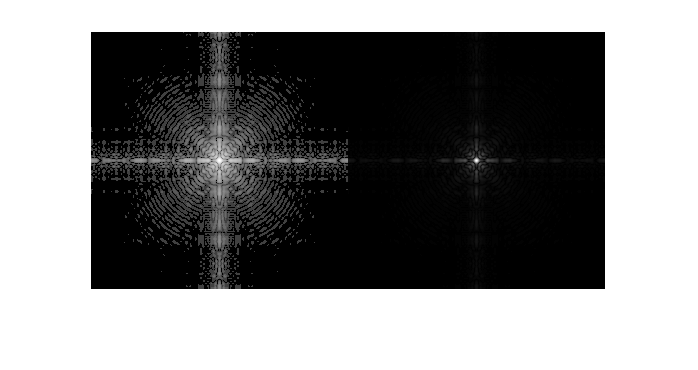


% met logarithmic transformation
g=im2uint8(mat2gray(log(1+double(im))));
imshowpair(g,im,'montage');